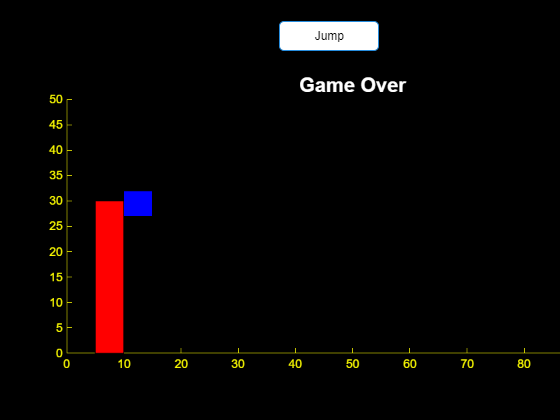

%% Geometry Dash Mini (Live Script Version)

% Clear and setup figure
clear; close all; clc;

fig = uifigure('Name', 'Geometry Dash Mini'); % UI Figure for live script compatibility
ax = uiaxes(fig, 'Position', [50 50 600 300]); % Creates axes on figure and the position sets the size and location inside the figure
axis(ax, [0 100 0 50]); % sets x and y ranges
hold(ax, 'on'); % Allows you to draw multiple shapes without deleting previous ones
ax.XColor = 'y'; % Sets x-axis color
ax.YColor = 'y'; % Sets y-axis color
ax.Color = 'k'; % Sets figure color(background color)
fig.Color = 'k'; % Sets outside figure color(edge background color)

% Add Jump Button
jumpButton = uibutton(fig, 'Text', 'Jump', 'Position', [280 370 100 30]); % Creates a jump button with text and the buttons position in the figure

% Player properties
%First two lines sets players dimensions, next two definings where the
%player is positioned, the next own gives the players vertical velocity
player.width = 5;
player.height = 5;
player.x = 10;
player.y = 10;
player.velocityY = 0;
gravity = -0.5; % Gravity pulls player down each frame
jumpVelocity = 8; % How fast the player move up while jumping

% Obstacle properties
obstacles = struct('x', {}, 'y', {}, 'width', {}, 'height', {}); % list that will hold all the obstacle blocks
spawnTimer = 0; % tracks time to know when to create a new obstacle

% Draw player
% Draws a blue rectangle representing the player cube using the player
% properties
playerRect = rectangle(ax, 'Position', [player.x player.y player.width player.height], 'FaceColor', 'b');

% Game control
running = true; % A flag to control if the game is still running

% Set jump function
jumpButton.ButtonPushedFcn = @(btn,event) jump(); % When the Jump button is clicked, it calls the jump function which is a local function at end of the script

%% Main Game Loop
% Keeps the game/code running until the player crashes or the figure pop-up
% is closed
while running && isvalid(fig)
    % Update player physics
    player.velocityY = player.velocityY + gravity; % Gravity reduces vertical speed every frame
    player.y = player.y + player.velocityY; % Vertical position updates using velocity
    
    %If player touches the ground(x-axis), stop falling further
    if player.y <= 0
        player.y = 0;
        player.velocityY = 0;
    end
    
    % Update player drawing
    playerRect.Position = [player.x player.y player.width player.height]; % Update the drawing of the player at the new position after the jump
    
    % Spawn obstacles
    %Every 100 frames it resets the timer and create a new obstacle at the far right (x=100), random height.
    spawnTimer = spawnTimer + 1;
    if spawnTimer > 100
        spawnTimer = 0;
        newObstacle.x = 100;
        newObstacle.y = 0;
        newObstacle.width = 5;
        newObstacle.height = 10 + randi(20);
        obstacles(end+1) = newObstacle;
    end
    
    % Move and update obstacles
    % Every frame, obstacles move left by 1 unit
    for i = 1:length(obstacles)
        obstacles(i).x = obstacles(i).x - 1;
    end
    
    % Delete obstacles that have moved off the screen
    obstacles = obstacles([obstacles.x] > -5);
    
    % Redraw obstacles
    % Clears old obstacle drawings and redraw all obstacles at new positions.
    delete(findobj(ax, 'Tag', 'obstacle'));
    for i = 1:length(obstacles)
        rectangle(ax, 'Position', [obstacles(i).x obstacles(i).y obstacles(i).width obstacles(i).height], ...
            'FaceColor', 'r', 'Tag', 'obstacle');
    end
    
    % Check collision
    % Check if player touches any obstacle and if yes, stop game and display "Game Over"
    for i = 1:length(obstacles)
        if rectsCollide(player, obstacles(i))
            running = false;
            title(ax, 'Game Over', 'Color', 'w', 'FontSize', 20);
            break;
        end
    end
    
    pause(0.03); % Frame pause to slow the loop down to ~30 frames per second (smooth motion) and can stop a auto game over before you actually get in the game
end


%% Jump Function
% When button clicked:
% If player is on the ground it set vertical velocity to jump up.
function jump()
    player = evalin('base', 'player');
    if player.y == 0
        player.velocityY = 8; % Jump up
        assignin('base', 'player', player);
    end
end

%% Collision Function
%Checks if two rectangles (player and obstacle) overlap.
% If they overlap then a collision happened.
function result = rectsCollide(a, b)
    result = ~(a.x + a.width < b.x || a.x > b.x + b.width || ...
               a.y + a.height < b.y || a.y > b.y + b.height);
end




%Extra from app

            % Set player properties again and environment properties
            player.length = 5; % m
            player.width = 5; % m
            player.Yposition = 0; % m
            jump_Yvelocity = 11; % m/s
            jump_Xvelocity = 5; % m/s
            gravity = -3; % m/s^2
            
            for t = linspace(0 , 22/3 , 100)

            y_jump = (jump_Yvelocity .* t) + (1/2 .* (gravity) .* t.^2);
            x_jump =  ((jump_Xvelocity .* t) + 10);
            pause(0.00000001)
            Player_orientation = rectangle(app.UIAxes, 'Position', [x_jump y_jump player.length player.width], 'FaceColor', 'b');

            end

Unable to resolve the name 'app.UIAxes'.



            for t = linspace(0 , 8 , 100) % Ranges from the time of the click to when the bottom edge of the square hits y = 0

            y_jump = (jump_Yvelocity .* t) + (1/2 .* (gravity) .* t.^2); % Controls vertical motion(projectile motion like)
            x_jump =  ((jump_Xvelocity .* t) + 10); % Sets X distance of each movement which is fixed at x = 10
            pause(0.001)
              
                Player_orientation = rectangle(app.UIAxes, 'Position', [x_jump y_jump player.length player.width], 'FaceColor', 'r' , 'EdgeColor', 'k');

            end


                %end

                if t == 2
                        Player_orientation = rectangle(app.UIAxes, 'Position', [x_jump y_jump player.length player.width], 'FaceColor', 'r' , 'EdgeColor', 'k');
                end



                if t == 6
                        Player_orientation = rectangle(app.UIAxes, 'Position', [x_jump y_jump player.length player.width], 'FaceColor', 'r' , 'EdgeColor', 'k');
                end


                if t == 8
                    Player_orientation = rectangle(app.UIAxes, 'Position', [x_jump y_jump player.length player.width], 'FaceColor', 'r' , 'EdgeColor', 'k');
                end



         dt = 0.05;  % time step
t = 0;

% Fixed X position
x_pos = 10;

% Clear previous drawings
cla(app.UIAxes);

% Set fixed axis limits and prevent auto-scaling

pbaspect(app.UIAxes, [1 1 1]);        % Preserve square shape
hold(app.UIAxes, 'on');

% Draw rectangle once and keep a handle to it
h = rectangle(app.UIAxes, ...
    'Position', [x_pos, player.Yposition, player.length, player.width], ...
    'FaceColor', 'r', 'EdgeColor', 'k');

% Animate
while true
    % Update time
    t = t + dt;

    % Calculate new Y position
    y_pos = jump_Yvelocity * t + 0.5 * gravity * t^2;

    % Stop when it hits the ground
    if y_pos <= 0
        y_pos = 0;
        h.Position = [x_pos, y_pos, player.length, player.width];
        drawnow;
        break;
    end

    % Update rectangle position
    h.Position = [x_pos, y_pos, player.length, player.width];

    pause(dt);
end

            xlim(app.UIAxes , [0 100]); % Sustains x-value range
            ylim(app.UIAxes, [0 100]); % Sustains y-value range
